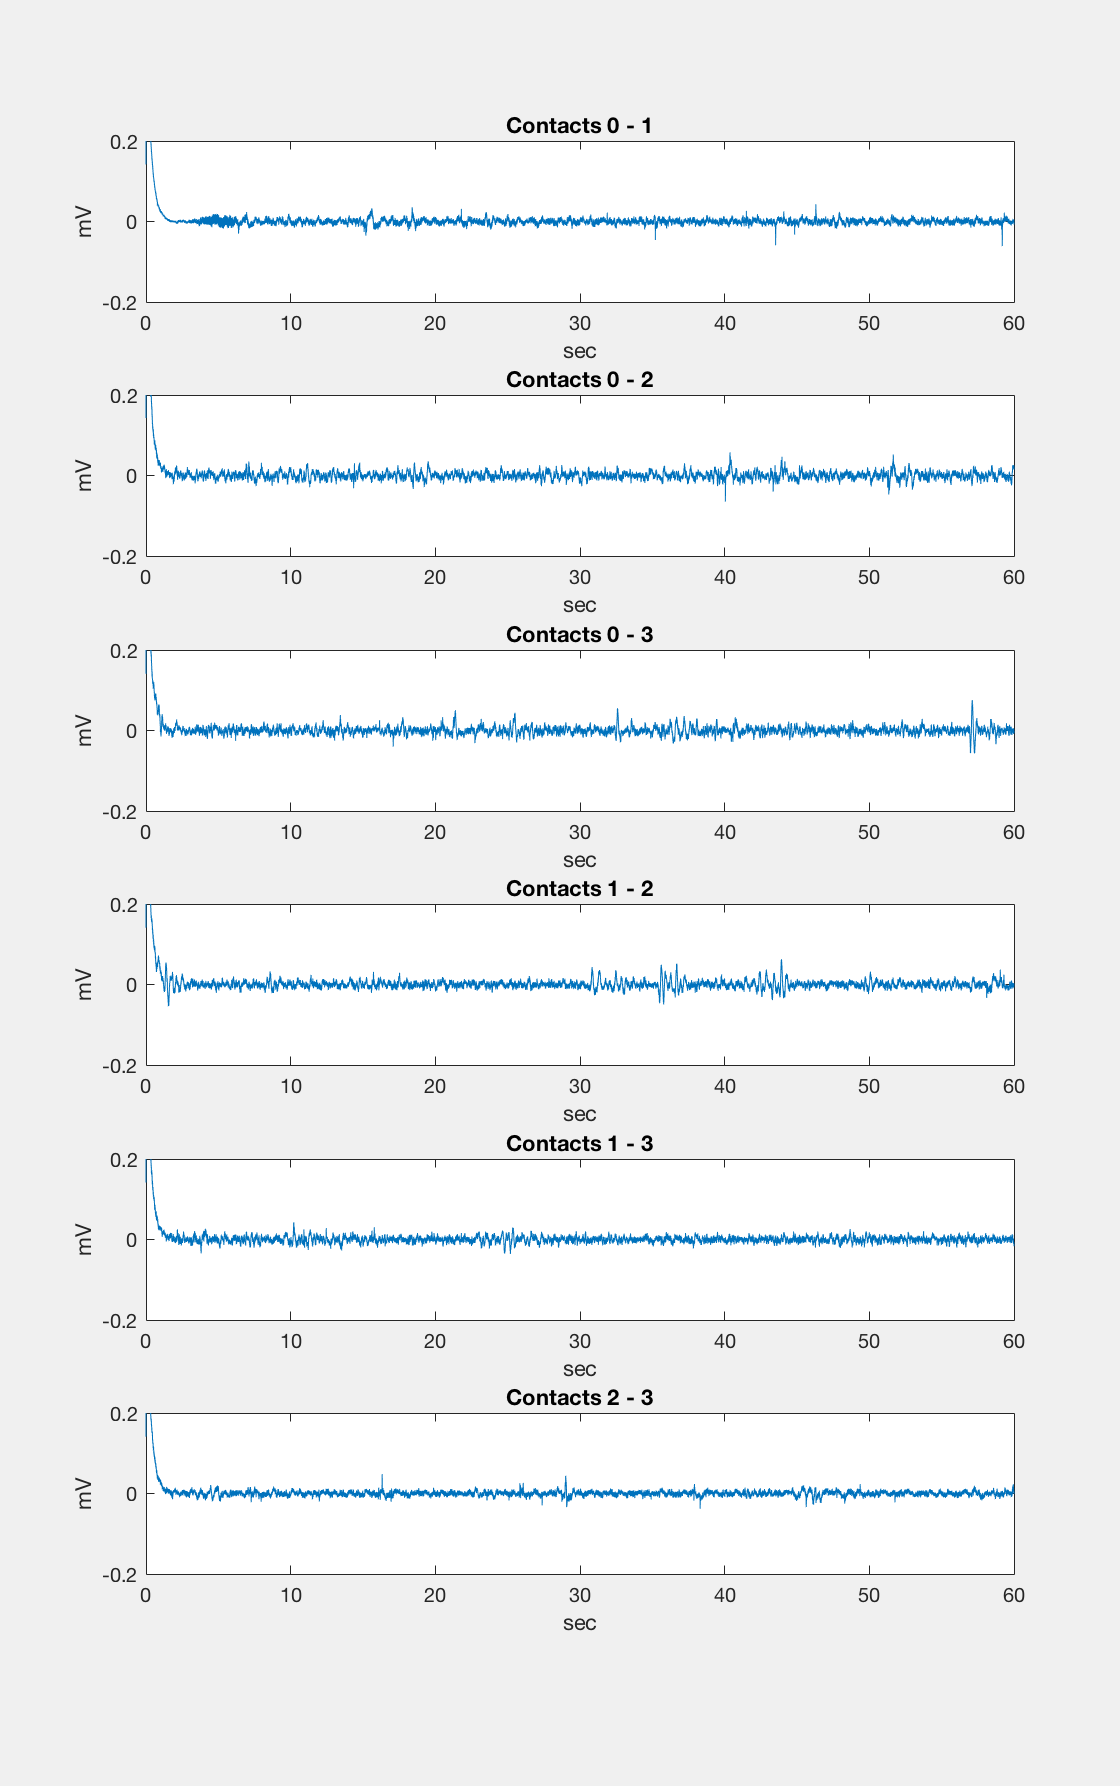

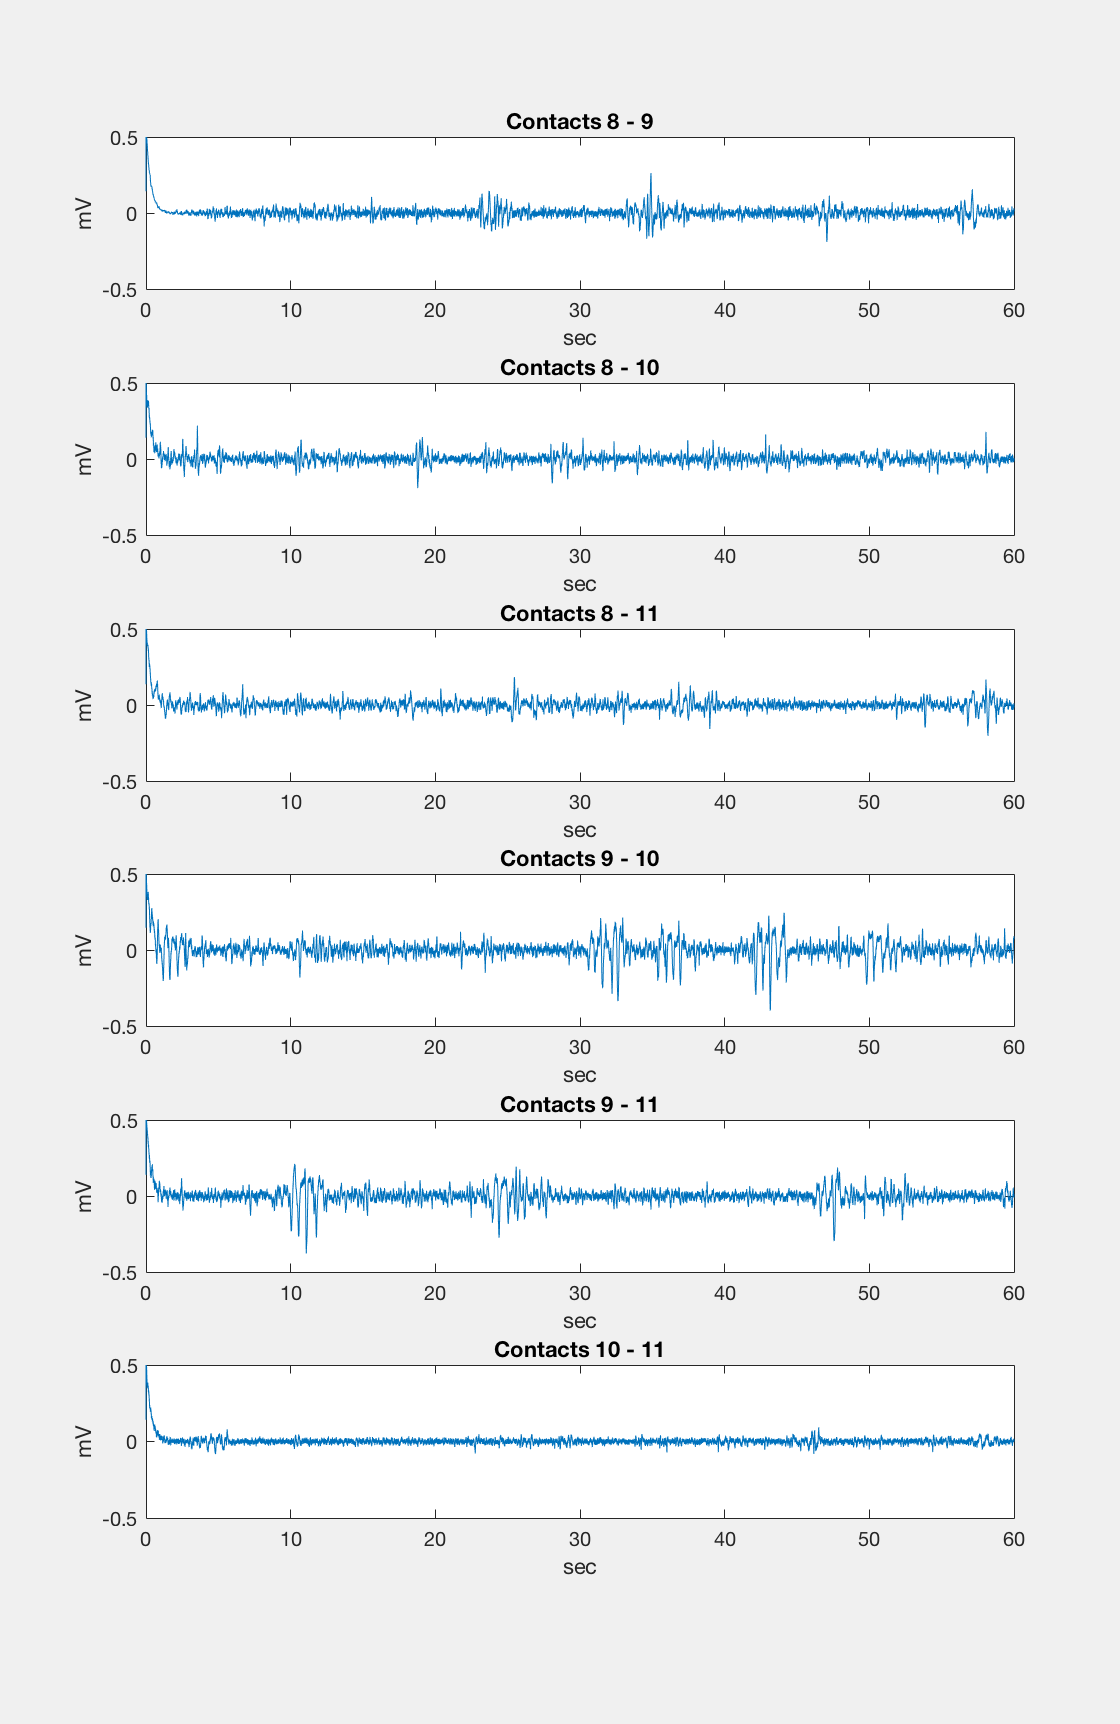

% Basic montage Analysis to determine best electode pair  
% This will plot a montage data from a selected folder
% 
% This will import the text files associated with a particular recording,
% and store it in a structure array for the time domain data, along with
% variables from the XML array

clear

dirname = fullfile('..','data','raw_data','Montage'); %take the raw data folder
% dinfo=dir(dirname);
% dinfo(1:3) = [];  %remove any dir starting with . 
% dirname = fullfile(dirname,dinfo(1).name);

% get the directory for the montage data.
dirname1 = uigetdir(dirname);

Fs=422; %Hz
duration = 60; %sec


addpath(genpath(fullfile(pwd,'toolboxes')));
filelist1 = findFilesBVQX(dirname1,'*_MR_*.txt');

ACCleads=[0 1;0 2;0 3;1 2;1 3;2 3];




% import the time domain data
numsessions = size(filelist1,1) ;
for f=1:numsessions
    raw1=importdata(filelist1{f});
    rawdata{f}.ACC= raw1(:,1); %columns 1 (ACC) and 3 (OFC) are time domain data 
    rawdata{f}.OFC= raw1(:,3); 
    
    xvals=linspace(0,duration,size(raw1,1));
    
figure(1)
subplot(numsessions,1,f)
plot(xvals,rawdata{f}.ACC);
ylabel('mV')
xlabel('sec')
ylim([-0.2 0.2])
title(sprintf('Contacts %d - %d',ACCleads(f,1),ACCleads(f,2)));


figure(2)
subplot(numsessions,1,f)
plot(xvals,rawdata{f}.OFC);
ylabel('mV')
xlabel('sec')
ylim([-0.5 0.5])
title(sprintf('Contacts %d - %d',ACCleads(f,1)+8,ACCleads(f,2)+8));


end

## Spectrogramc ACC and OFC

The distribution of power values in rightward skewed, many more small power vals. So, Zscoring isn't strictly applicable, but people do it. 

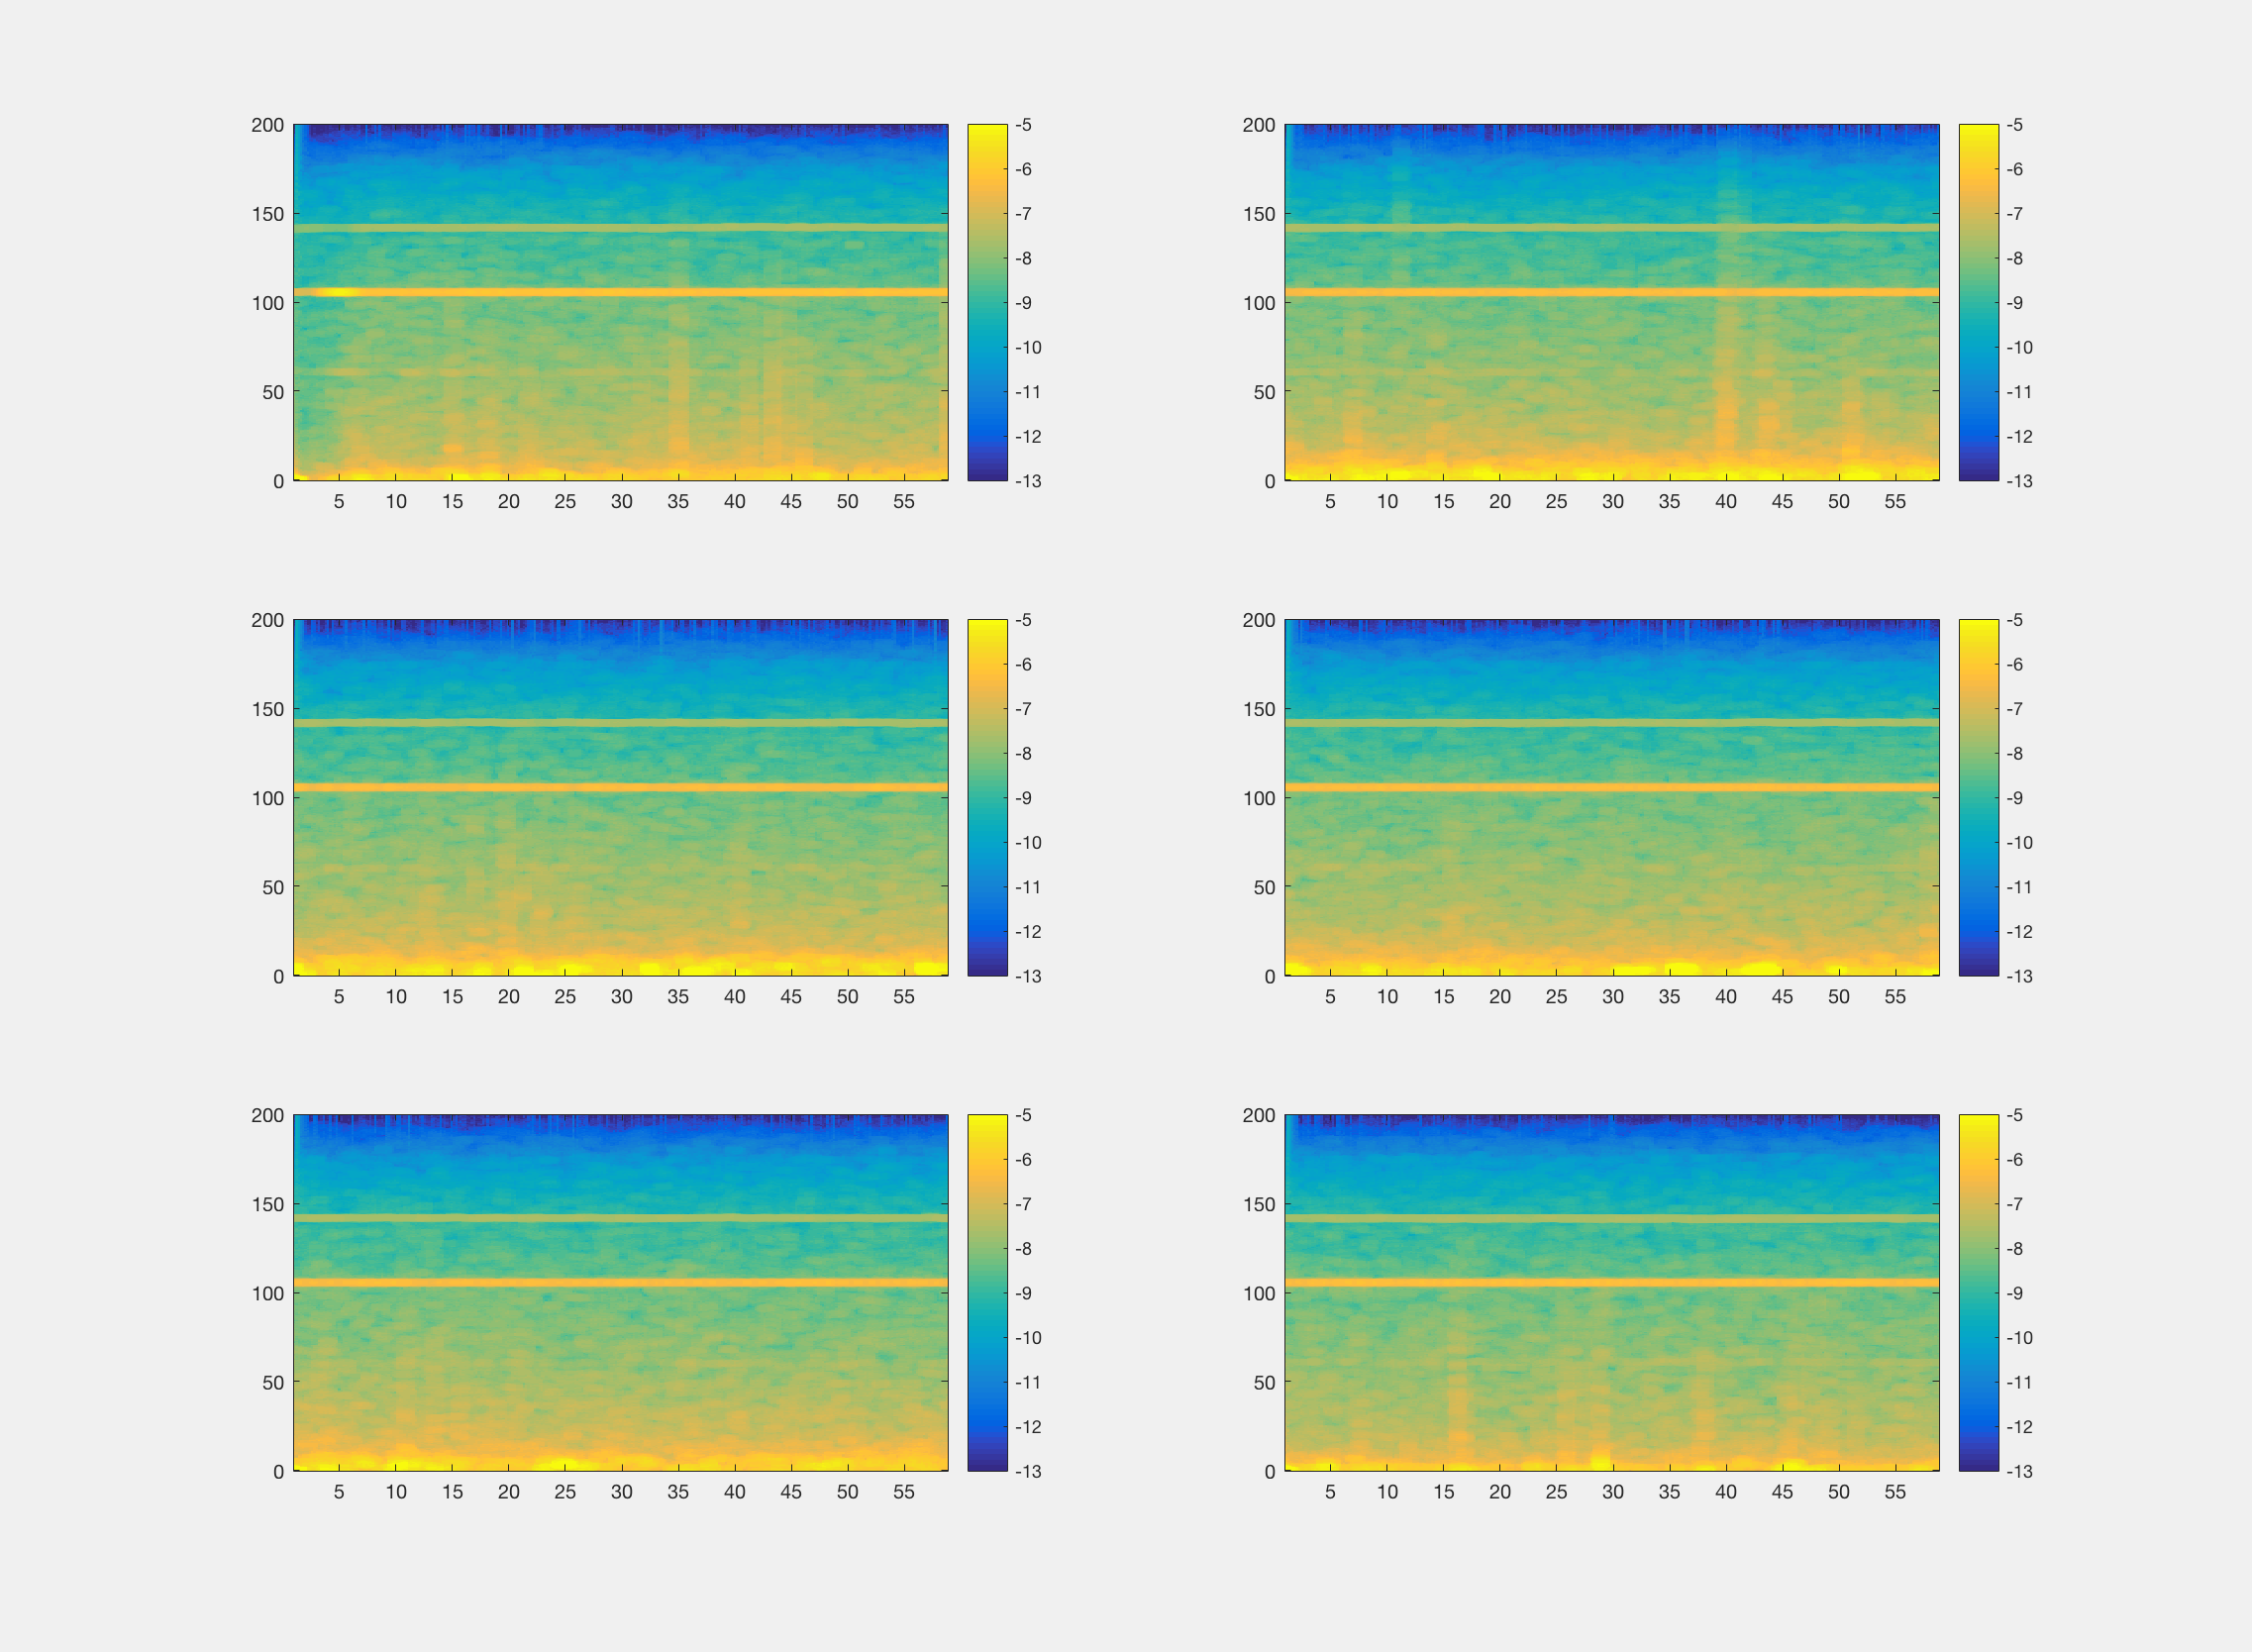

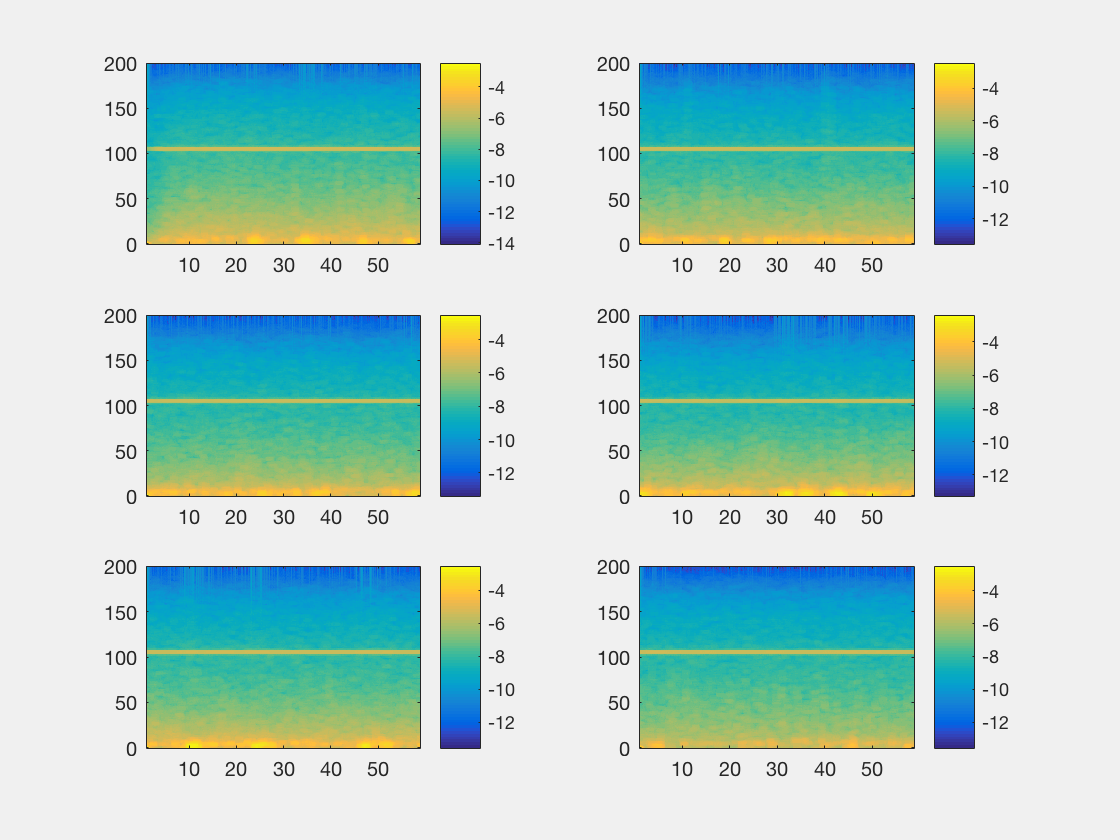

params.tapers = [5 7];
params.Fs=Fs;
params.pad=-1;
params.fpass=([0 200]);
for f= 1:size(rawdata,2)
   
    [S{f},t1{f},fq]= mtspecgramc(rawdata{f}.ACC,[2 0.2],params);
    figure (3)
    subplot(3,2,f)
    imagesc(t1{f},fq,(log10(S{f}'))); axis xy; colorbar; 
    caxis ([-13 -5])
    
    [S{f},t1{f},fq]= mtspecgramc(rawdata{f}.OFC,[2 0.2],params);
    figure (4)
    subplot(3,2,f)
    imagesc(t1{f},fq,(log10(S{f}'))); axis xy; colorbar; 
%     caxis ([-10 -4])
end

## just plotting

x=3
imagesc(t1{x},fq{x},log10(S{x}')); axis xy; colorbar

## Spectrum C

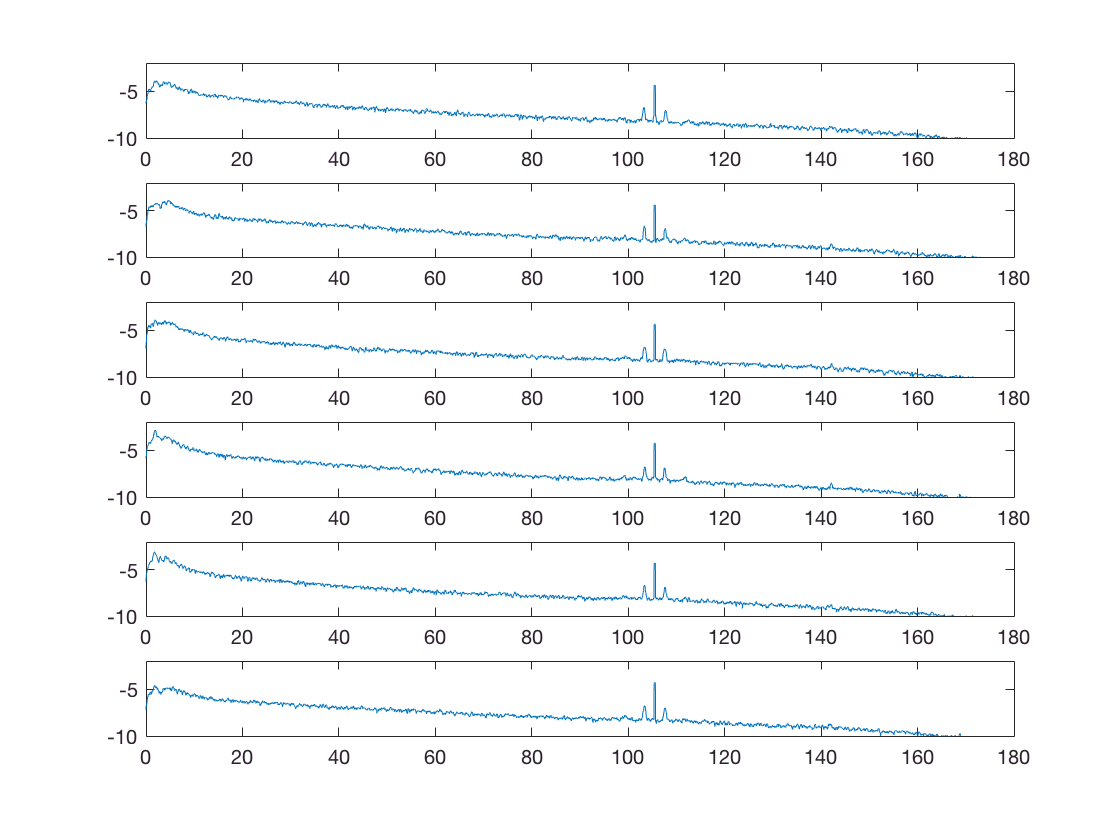

params.tapers = [10 14];
params.Fs=Fs;
params.pad=-1;
params.fpass=([0 200]);
for f= 1:size(rawdata,2)
    [S{f},fq]= mtspectrumc(rawdata{f}.OFC,params);

    subplot(6,1,f)
    plot(fq,log10(S{f}')); axis xy; ylim([-10 -2]);
end